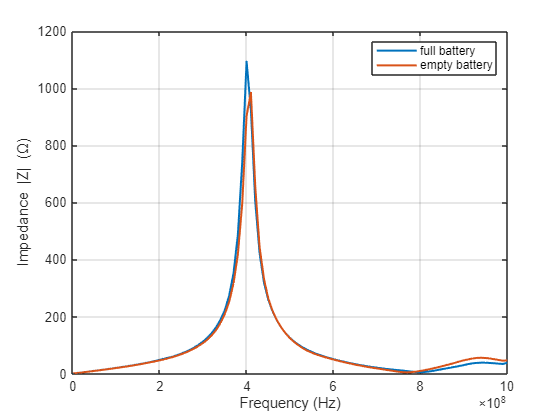

% Here we plot the measurement of a full and empty battery, done with the
% vna upto 1GHz on the PCB

Zf0 = zparameters('nanovna_battery_full_1GHz.s2p');
Zf = zparameters('nanovna_battery_empty_1GHz.s2p');
zf110 = rfparam(Zf0,1,1);
zf11 = rfparam(Zf,1,1);
plot(Zf.Frequencies, abs(zf11),'LineWidth', 1.5, 'DisplayName', 'full battery') ;% this is for imaginary part of Z-, change as per your requrements
hold on; % Maintenir le même graphique
plot(Zf.Frequencies, abs(zf110), 'LineWidth', 1.5,'DisplayName', 'empty battery') ;% this is for imaginary part of Z-, change as per your requrements
hold off; % Libérer le graphique

xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend; % Afficher 

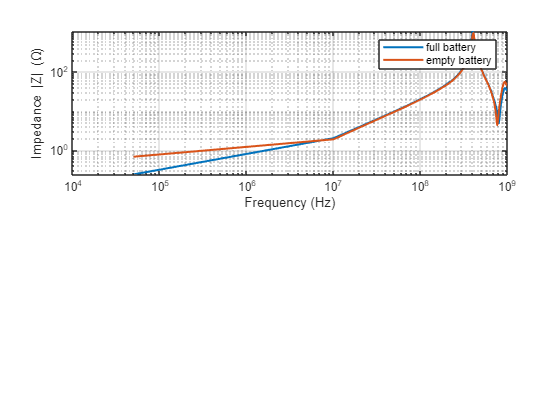

% Same here but with logarithmic scale

% Load the .s2p file
sparamsf = sparameters('nanovna_battery_empty_1GHz.s2p'); % path of the file
sparamsf0 = sparameters('nanovna_battery_full_1GHz.s2p'); % path of the file

frequencyf = sparamsf.Frequencies; 
frequencyf0 = sparamsf0.Frequencies; 

S11f = squeeze(sparamsf.Parameters(1,1,:)); % S11 complexe
S11f0 = squeeze(sparamsf0.Parameters(1,1,:)); % S11 complexe

Z0 = 50; % Ohms

% Impedance calculation
Zf = Z0 * (1 + S11f) ./ (1 - S11f);
Zf0 = Z0 * (1 + S11f0) ./ (1 - S11f0);

Z_magnitudef = abs(Zf);
Z_magnitudef0 = abs(Zf0);


figure;
subplot(2,1,1)
loglog(frequencyf, Z_magnitudef, 'LineWidth', 1.5, 'DisplayName', 'full battery');
hold on; 
loglog(frequencyf0, Z_magnitudef0, 'LineWidth', 1.5,'DisplayName', 'empty battery');
hold off;



xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend; 

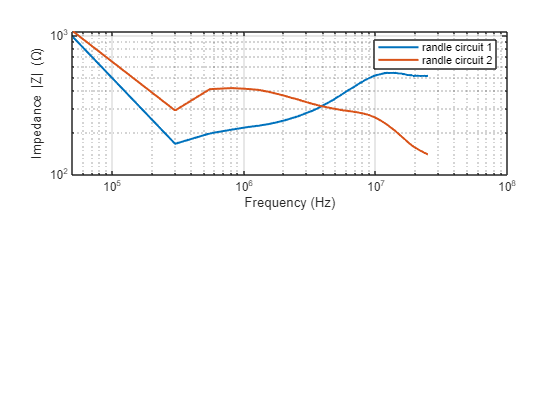

% Measurement of the two randle circuit on PCB upto 25 MHz

% Load the .s2p file
sparamsf = sparameters('Randle 1 - 25MHz.s2p'); % path of the file
sparamsf0 = sparameters('Randle 2 - 25MHz.s2p'); % path of the file

frequencyf = sparamsf.Frequencies; 
frequencyf0 = sparamsf0.Frequencies; 

S11f = squeeze(sparamsf.Parameters(1,1,:)); % S11 complexe
S11f0 = squeeze(sparamsf0.Parameters(1,1,:)); % S11 complexe

Z0 = 50; % Ohms

% Impedance calculation
Zf = Z0 * (1 + S11f) ./ (1 - S11f);
Zf0 = Z0 * (1 + S11f0) ./ (1 - S11f0);

Z_magnitudef = abs(Zf);
Z_magnitudef0 = abs(Zf0);


figure;
subplot(2,1,1)
loglog(frequencyf, Z_magnitudef, 'LineWidth', 1.5, 'DisplayName', 'randle circuit 1');
hold on; 
loglog(frequencyf0, Z_magnitudef0, 'LineWidth', 1.5,'DisplayName', 'randle circuit 2');
hold off;



xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend; 

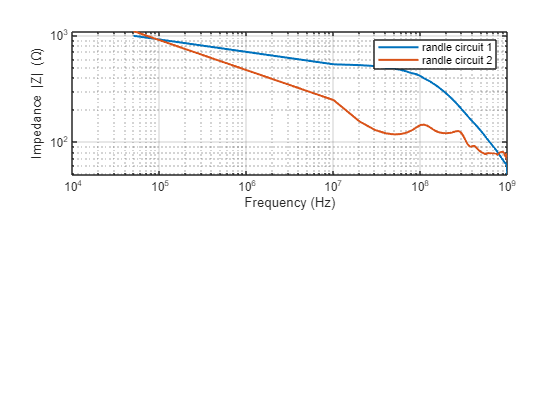

% Measurement of the two randle circuit on PCB upto 1 GHz

% Load the .s2p file
sparamsf = sparameters('Randle1-1MHz.s2p'); % path of the file
sparamsf0 = sparameters('Randle 2 - 1GHz.s2p'); % path of the file

frequencyf = sparamsf.Frequencies; 
frequencyf0 = sparamsf0.Frequencies; 

S11f = squeeze(sparamsf.Parameters(1,1,:)); % S11 complexe
S11f0 = squeeze(sparamsf0.Parameters(1,1,:)); % S11 complexe

Z0 = 50; % Ohms

% Impedance calculation
Zf = Z0 * (1 + S11f) ./ (1 - S11f);
Zf0 = Z0 * (1 + S11f0) ./ (1 - S11f0);

Z_magnitudef = abs(Zf);
Z_magnitudef0 = abs(Zf0);


figure;
subplot(2,1,1)
loglog(frequencyf, Z_magnitudef, 'LineWidth', 1.5, 'DisplayName', 'randle circuit 1');
hold on; 
loglog(frequencyf0, Z_magnitudef0, 'LineWidth', 1.5,'DisplayName', 'randle circuit 2');
hold off;



xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend; 

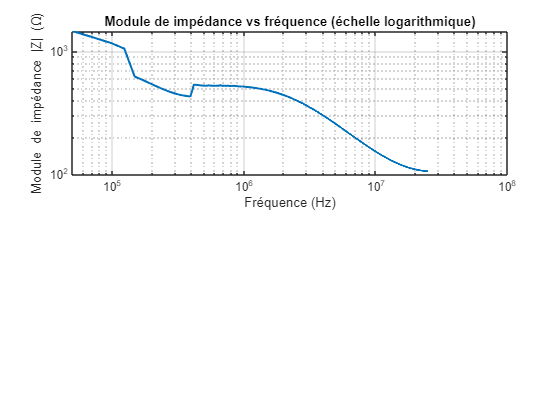

% Measurement of the two second randle circuit on breadboard upto 25MHz
% with the VNA

% Load the .s2p file
sparams = sparameters('secondorders21.s2p'); % Path to the file


frequency = sparams.Frequencies; 

S11 = squeeze(sparams.Parameters(1,1,:));


Z0 = 50; % Ohms

% Impedance calculation
Z = Z0 * (1 + S11) ./ (1 - S11);


Z_magnitude = abs(Z);


figure;
subplot(2,1,1)
loglog(frequency, Z_magnitude, 'LineWidth', 1.5);
xlabel('Fréquence (Hz)');
ylabel('Module de impédance |Z| (\Omega)');
grid on;
title('Module de impédance vs fréquence (échelle logarithmique)');

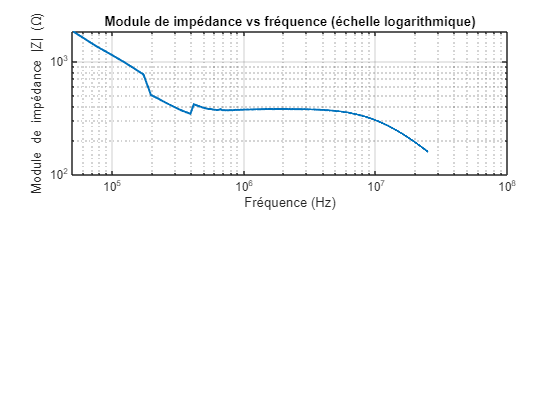

% Measurement of the two first randle circuit on breadboard upto 25MHz
% with the VNA

% Load the .s2p file
sparams2 = sparameters('firstorder25.s2p'); % Remplacez par le chemin du fichier


frequency4 = sparams2.Frequencies; % Fréquence en Hz


S113 = squeeze(sparams2.Parameters(1,1,:)); % S11 complexe


Z0 = 50; % Ohms

% Impedance calculation
Z3 = Z0 * (1 + S113) ./ (1 - S113);


Z_magnitude3 = abs(Z3);


figure;
subplot(2,1,1)
loglog(frequency4, Z_magnitude3, 'LineWidth', 1.5);
xlabel('Fréquence (Hz)');
ylabel('Module de impédance |Z| (\Omega)');
grid on;
title('Module de impédance vs fréquence (échelle logarithmique)');

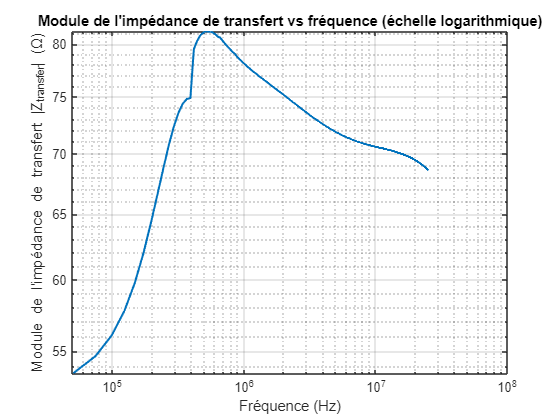

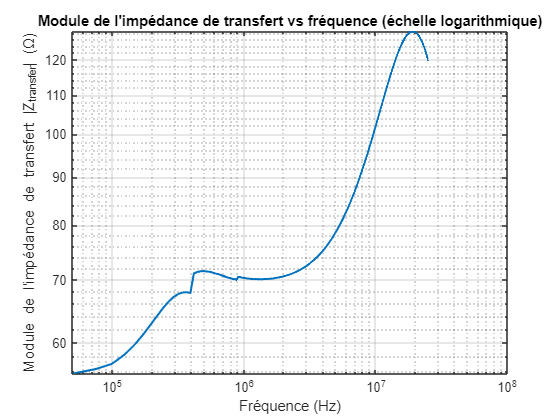

% Here we plot the result of the lt spice on breadboard.

% Load the file

donnee1 = Randlecircuit1; % For this data you need to add the file Randlecircuit1.txt as data on matlab

Unrecognized function or variable 'Randlecircuit1'.

donnee2 = randlecircuit2; % For this data you need to add the file randlecircuit2.txt as data on matlab




frequence = donnee1{:, 1}; 
impedanceltpice1 = donnee1{:, 2};

frequence2 = donnee2{:, 1}; 
impedanceltpice2 = donnee2{:, 2};






figure;
subplot(2,1,1)
loglog(frequence, impedanceltpice1, 'LineWidth', 1.5, 'DisplayName', 'lt first');
hold on;
loglog(frequence2, impedanceltpice2, 'LineWidth', 1.5, 'DisplayName', 'lt second');
hold off; 


xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend; 

% Here we compare the result of ltspice, vna and analog discovery 2 on breadboard.

% Load the file

data = Randlecircuit2ndorder25MHzversion1pcb; % For this data you need to add the file Randlecircuit2ndorder25MHzversion1pcb.txt as data on matlab
data2 = Randlecircuit1storder25MHzversion1pcb; % For this data you need to add the file Randlecircuit1storder25MHzversion1pcb.txt as data on matlab




frequency2 = data{:, 1}; 
impedance = data{:, 3};

frequency3 = data2{:, 1}; 
impedance2 = data2{:, 3};






figure;
subplot(2,1,1)
loglog(frequency3, impedance2, 'LineWidth', 1.5, 'DisplayName', 'ad2 first');
hold on; 
loglog(frequency2, impedance, 'LineWidth', 1.5, 'DisplayName', 'ad2 second');
loglog(frequency, Z_magnitude, 'LineWidth', 1.5, 'DisplayName', 'VNA Lite second');
loglog(frequency4, Z_magnitude3, 'LineWidth', 1.5, 'DisplayName', 'VNA Lite first');
loglog(frequence2, impedanceltpice2, 'LineWidth', 1.5, 'DisplayName', 'lt second');
loglog(frequence, impedanceltpice1, 'LineWidth', 1.5, 'DisplayName', 'lt first');
hold off;


xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend; 


figure;
subplot(2,1,1)
loglog(frequency3, impedance2, 'LineWidth', 1.5, 'DisplayName', 'ad2 first');
hold on; 
loglog(frequency4, Z_magnitude3, 'LineWidth', 1.5, 'DisplayName', 'VNA Lite first');
loglog(frequence, impedanceltpice1, 'LineWidth', 1.5, 'DisplayName', 'lt first');
hold off;


xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend;  


figure;
subplot(2,1,1)
loglog(frequency2, impedance, 'LineWidth', 1.5, 'DisplayName', 'ad2 second');
hold on; 
loglog(frequency, Z_magnitude, 'LineWidth', 1.5, 'DisplayName', 'VNA Lite second');
loglog(frequence2, impedanceltpice2, 'LineWidth', 1.5, 'DisplayName', 'lt second');
hold off; 


xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend;  

% Here we plot the result of the lt spice on breadboard.

% Load the file


donnee1alt = Randlecircuit1alt; % For this data you need to add the file Randlecircuit1alt.txt as data on matlab
donnee2alt = randlecircuit2alt; % For this data you need to add the file randlecircuit2alt.txt as data on matlab




frequencealt = donnee1alt{:, 1};
impedanceltpice1alt = donnee1alt{:, 2};

frequence2alt = donnee2alt{:, 1}; 
impedanceltpice2alt = donnee2alt{:, 2};





figure;
subplot(2,1,1)
loglog(frequence, impedanceltpice1, 'LineWidth', 1.5, 'DisplayName', 'lt first');
hold on; 
loglog(frequencealt, impedanceltpice1alt, 'LineWidth', 1.5, 'DisplayName', 'lt first alt');
hold off;


xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend;  


figure;
subplot(2,1,1)
loglog(frequence2, impedanceltpice2, 'LineWidth', 1.5, 'DisplayName', 'lt second');
hold on; 
loglog(frequence2alt, impedanceltpice2alt, 'LineWidth', 1.5, 'DisplayName', 'lt second alt');
hold off; 


xlabel('Frequency (Hz)');
ylabel('Impedance |Z| (\Omega)');
grid on;
legend; 